# **Lab 1 - Q2**

## **Question 2**

Suppose we have a discrete FIR filter with an impulse response $h\left\lbrack n\right\rbrack$ given by:


$$h\left\lbrack n\right\rbrack =\left\lbrack -0\ldotp 0625,0\ldotp 25,0\ldotp 625,0\ldotp 25,-0\ldotp 0625\right\rbrack$$


### Part (a)

We want to apply this filter to the sequence, $x\left\lbrack n\right\rbrack$ given by:


$$x\left\lbrack n\right\rbrack =\left\lbrace 1,2,3,4,5,6,7,6,5,4,3,2,1\right\rbrace$$


The filter needs to applied by a custom implementation of the convolution operation give as:


$$\mathit{\mathbf{y}}=\sum_n x\left\lbrack n\right\rbrack {\mathit{\mathbf{h}}}_n \;\;\;\;\;\;\left(1\right)$$


Where ${\mathit{\mathbf{h}}}_{\mathit{\mathbf{n}}}$ is the filter's impulse response as a vector (generally a column vector) whereby each element of the impulse response is delayed by $n$ samples. In this implementation, the samples $x\left\lbrack n\right\rbrack$ serve as coeffcients for each vector ${\mathit{\mathbf{h}}}_{\mathit{\mathbf{n}}}$. A linear combination of these vectors will produce the output vector $\mathit{\mathbf{y}}$. Since this implementation is reliant on scanning for each element of the input sequence, this method is appropriately named as the **input-based** approach to convolution. The alternative definition which we can directly use is:


$$y\left\lbrack n\right\rbrack =\sum_k h\left\lbrack k\right\rbrack x\left\lbrack n-k\right\rbrack =\left(h\star x\right)\left\lbrack n\right\rbrack \;\;\;\;\;\left(2\right)$$


The following code attempts to directly implment variation (1) as we only require two loops and an appropriate way to perform a sample delay.

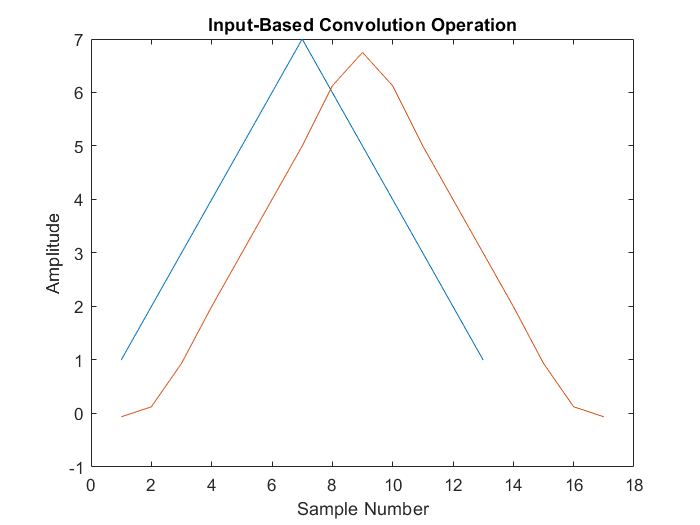

% Initialise filter, h. Will be a column vector soon.

h_og = [-0.0625, 0.25, 0.625, 0.25, -0.0625];

% Initialise the input signal, x. Keep this as a row-vector

x = [1,2,3,4,5,6,7,6,5,4,3,2,1];

% Let the length of the input signal be N
% Let the length of the filter be M

N = length(x);
M = length(h_og);

% The length of the output of the convolution MUST be
% N + M - 1. We allocate this space for the output vector.
% Transform into a column vector as well.

L = M + N - 1;
y = zeros([L,1]);

% Prior to the convolution, we need to ensure the length of the filter's
% column vector is equal to the length the output vector. This is not only
% to ensure the dimensions match, but that there is sufficient space in the
% filter's column vector that allows us to induce sample delay as per the
% convolution equation definition. We append (L-M) zeros to the impulse response 
% vector. Transform the impulse response row vector into a column vector.

tmp_zeros = zeros([1, L-M]);
h = [h_og, tmp_zeros];
h = transpose(h);

% Apply input-based convolution based on the equation above as per the
% intro. We can think of the output vector formed by the linear combination
% of the filters' response as a column vector with coefficients based on
% the elements of the input sequence. This means we have a loop that loops
% through each element of the input sequence and performs the sum as shown.

for n = 0:N-1

    % Shift the filter's impulse response by the right number of samples.
    % Change into a column vector thereafter.
    h_n = [zeros(1, n) h_og zeros(1, length(h) - length(h_og) - n)];
    h_n = transpose(h_n);
    
    % Apply the convolution by appending result onto the current result for
    % the output vector, y.
    y = y + (x(n+1) * h_n);
    
end

% Proceed to plot the original and convolved signal. We should expect some
% sort of time-shift as well in the output-signal:
figure(1)
plot(x)
hold on
plot(y)
title("Input-Based Convolution Operation")
ylabel("Amplitude")
xlabel("Sample Number")

### Part (b)

We now want to perform the exact same convolution but using an **output-based** implementation. In this case, we look to perform the convolution for each individual sample in the output sequence on a sample-by-sample basis. This can be achieved by using the inner-product definition of the convolution.


$$y\left\lbrack n\right\rbrack =\left\langle \mathit{\mathbf{x}},\tilde{{\mathit{\mathbf{h}}}_n } \right\rangle$$


Where $\mathit{\mathbf{x}}$ is the input-sequence as a column vector and $\tilde{\;{\mathit{\mathbf{h}}}_{\mathit{\mathbf{k}}} }$ is the filter's impulse response that has been time-reversed and delayed by $\mathit{\mathbf{n}}$ samples to the right. The time-reversal can be described by the following equation:


$$\mathit{\mathbf{h}}=\tilde{\;h} \left\lbrack n\right\rbrack =h\left\lbrack -n\right\rbrack$$


Implmentation-wise, since both the input and filter's sequences are both discrete and real, we may treat the inner-product equation as effectively the **dot-product** between the input sequence column vector and the time-reversed filter's impulse response column vector. The result of the dot-product, of course, is a single scalar that is assigned to the current output sample being accessed in, perhaps, a for-loop. In summary, the steps are:

- Initialise the filter (kernel)

- Flip (time-reverse) the kernel

- Zero-pad the input signal sequence at beginning and end

- Compute the dot product starting from the beginning of the signal.

- Move the filter kernal across the signal, computing dot products along the way

- Remove the zero-padding.

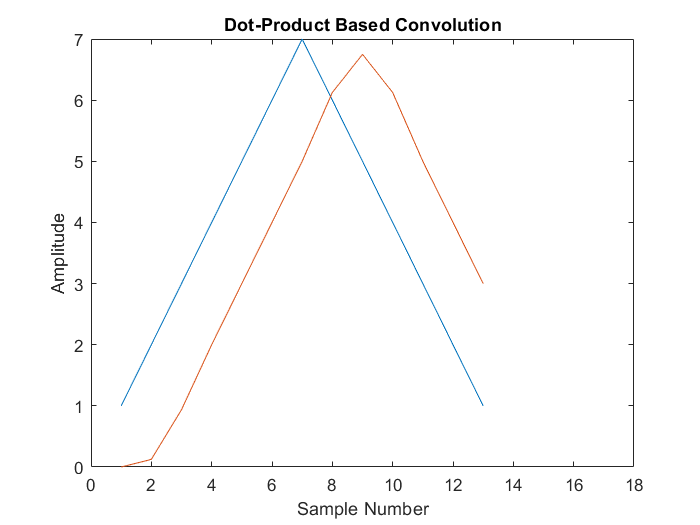

% Filter kernel. Flip the kernel too:
h = [-0.0625, 0.25, 0.625, 0.25, -0.0625];
h_flip = flip(h);

% Input signal sequence. Need to zero pad the signal as well. Number of
% zeros equal to the length of the filter kernel (5 samples)
x = [1,2,3,4,5,6,7,6,5,4,3,2,1];
x = [zeros(1,4), x, zeros(1,4)];

% Initialise the output sequence as an array of zeros. Length equal to the
% zero-padded input signal sequence.
y = zeros(1, length(x));

% Use a for-loop, use a moving window to extract a part of the input
% sequence with window length equal to the kernel size. Then, perform the
% dot-product and assign it to the appropriate sample in the output
% sequence.
for n = 1:length(y) - length(h)
    x_portion = x(n:n+length(h)-1);
    y(n) = sum(x_portion .* h_flip);
end

% Once the dot-product convolution is complete, we can now plot the signal
% (remove zero-padding from plot)
figure(3)
plot( x(length(h):end - length(h) + 1) )
hold on
plot(flip(y(length(h):end - length(h) + 1)))
xlim([0,18])
title("Dot-Product Based Convolution")
ylabel("Amplitude")
xlabel("Sample Number")

### Part (c)

We now want to investigate the magnitude and phase spectra of the filter, $\hat{h} \left(\omega \;\right)$ for the domain $-\pi \le \omega \le \pi \;$(i.e. normalised frequency). We need to create a custom DFT function once more that is able to compute both spectra. Call the function *norm_dft* that takes in the discrete signal and produces the discrete magnitude and phase spectra.

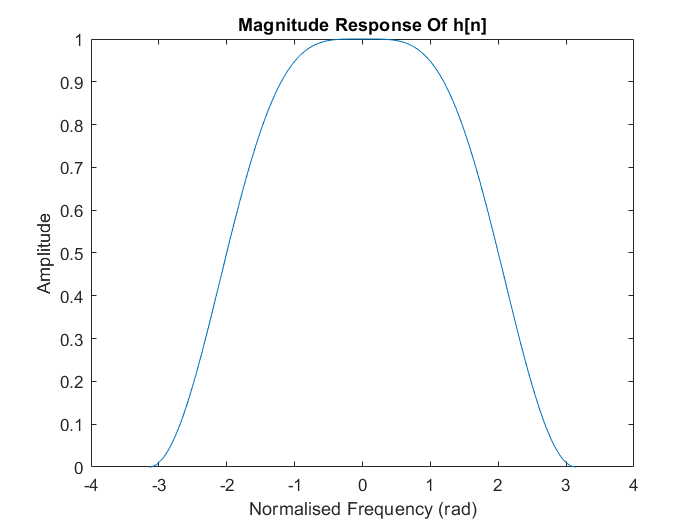

[omega, X_mag, phase_spec] = norm_dft(h, 1024);

% Need to shift the samples using fftshift to get the proper magnitude
% response.

figure(4)
plot(omega, fftshift(X_mag))
xlabel("Normalised Frequency (rad)")
ylabel("Amplitude")
title("Magnitude Response Of h[n]")

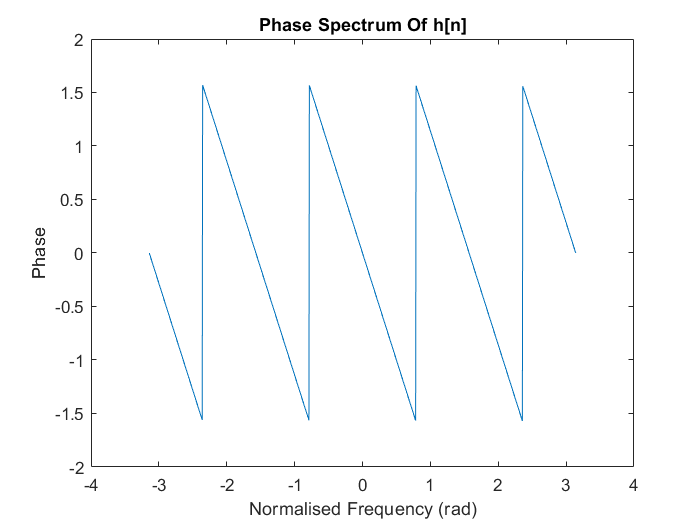


figure(5)
plot(omega, unwrap(phase_spec))
xlabel("Normalised Frequency (rad)")
ylabel("Phase")
title("Phase Spectrum Of h[n]")

**Discussion Of Results**

The magnitude and phase spectra reveal some of the properties of this small sized filter kernel. 

The phase spectrum, $\phi \;\left(\omega \;\right)$ shows linear phase behaviour (shown as a wrapped spectrum (inverted at discontinuities) but when properly unwrapped shows a straight line) which is characteristic of an FIR (*Finite Impulse Response*) filter. This ensures that the filter induces no phase distortion on the input signal when producing the output, hence, preserving the waveshape as much as possible. The negative derivative of the phase gives the ***group delay*** of the signal which can be expressed as:


$$\tau {\;}_g \left(\omega \;\right)=-\frac{d\phi \;}{\;d\omega \;}$$


The derivative of a linear graph is a constant non-zero horizontal line (since the linear phase spectrum has a gradient). The group delay indicates how much delay each sample of the output sequence will experience relative to the input signal. In this case, since the derivative is constant, the output sequence will experience a fixed group delay for all samples which is evident from the overall shift in the output sequence by 2 samples.

The magnitude response is characteristic of that for a window function whose responsibility is to attenuate the sidelobes in the frequency spectrum of the input signal (i.e. minimise the spectral leakage). 

### **Part (d)**

We now want to perform parts (a) to (c) for a new filter, $h_2 \left\lbrack n\right\rbrack$ given as:


$$h_2 \left\lbrack n\right\rbrack =\left\lbrack -0\ldotp 1,0\ldotp 6,0\ldotp 6,-0\ldotp 1\right\rbrack$$


The same input signal sequence will apply in this case. That is: 


$$x\left\lbrack n\right\rbrack =\left\lbrace 1,2,3,4,5,6,7,6,5,4,3,2,1\right\rbrace$$


#### Part I - Input-Based Convolution

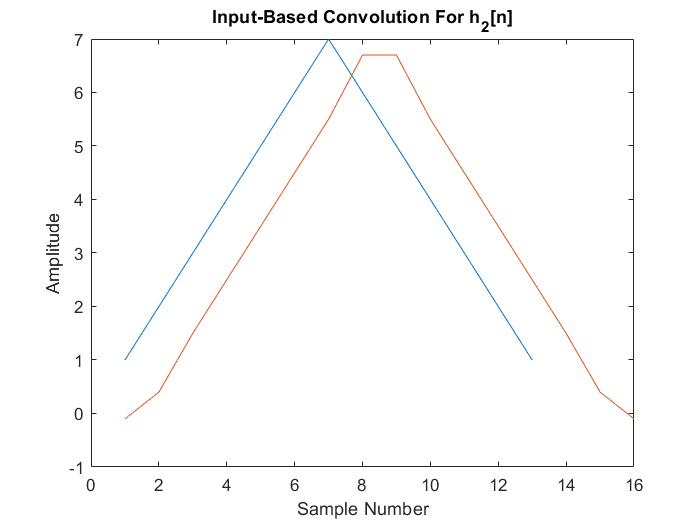

% Initialise brand new filter kernel, h2[n]:
h2 = [-0.1, 0.6, 0.6 -0.1];

% Initialise the signal once more:
x = [1,2,3,4,5,6,7,6,5,4,3,2,1];

% Let the length of the filter kernel be M. Let the length of the input
% sequence be N. Let the length of the intended convolved output be L. 
N = length(x);
M = length(h2);
L = M + N - 1;

% Initialise the output sequence to be an array of zeros of size L x 1. Let
% the output be y2.
y2 = zeros(L,1);

% Perform the convolution in the for-loop with respect to the length of the
% input sequence.
for n = 1:N
    
    % We need to pad the filter kernel with zeros such that its length is
    % the same as the length of the output sequence. There should be NO
    % induced shift for n = 1.
    h2_n = [zeros(1,n-1), h2, zeros(1, length(y2) - (n-1) - length(h2))];
    h2_n = transpose(h2_n);
    
    % Perform the linear sum using the input sequence samples as the source
    % of coefficients for the sum of vectors:
    y2 = y2 + (x(n) * h2_n); 
    
end

% Plot the input and output sequence for comparison:
figure(6)
plot(x)
hold on
plot(y2)
title("Input-Based Convolution For h_2[n]")
xlabel("Sample Number")
ylabel("Amplitude")

#### Part II - Output-Based (Dot-Product) Convolution

% Need to zero-pad the filter kernel at beginning and end of sequence.
% Call this modified array 'h2_pad'. Amount of padding equal to the length
% of the filter kernel.
h2_pad = [zeros(1,length(h2)), h2, zeros(1,length(h2))];

% Initialise the output vector with length N + M - 1
y2_2 = zeros(L,1);

% Perform dot-product convolution by extracting a portion of the input
% sequence with length equal to zero-padded filter kernel. This portion is
% then dot multiplied with the filter kernel shifted to the appropriate
% sample in the input-sequence and flipped before the multiplication. Loop
% is performed with respect to the length of the output sequence.
for n = 1:length(y2_2) - length(h2_p)
    y2_2(n) = sum(x(n:n+length(h2_pad) - 1) .* flip(h2_pad))
end

Unrecognized function or variable 'h2_p'.


% Plot the input and output sequence in the same fashion as part (c)
figure(7)
plot(x)
hold on
plot(flip(y2_2))